Jordan Grotz

2/21/2023

Capsule Robot Path Planning

First we must understand the scale of the provided image so we properly set the scale of the robot. The top opening is 17.1mm. We can determine pixel width by finding the pixel width of that same opening. The points designated were (832,171) and (680,154).

Next we want to properly store the lung map for easy searching. Currently, it is an RGB file, but we can binarize it to make it a series of ones and zeros. 1 is an obstacle, and 0 is an open space

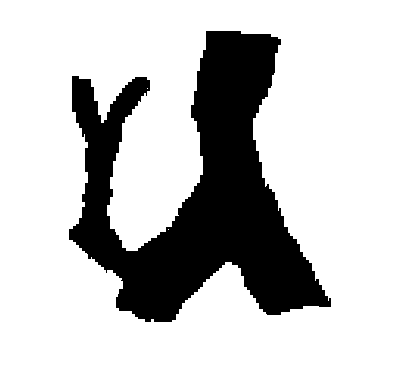

clear all 
clc

lung = imread("939-Oblique.png");
image_size = size(lung);
x_dim = image_size(1);
y_dim = image_size(2);
binary_image = double(lung(:,:,1) < 1);
%crop image to reduce computation times
final_field = binary_image(122:764,354:977,:);
imshow(final_field);

pixel_size = 17.1/(832-680); %mm
cells_per_mm = round(1/pixel_size); 


Capsule Size

10mm length by 5mm diameter represented as a 10x5mm rectangle as a 2d projection. The capsule can move in the x, y and rotate around its center. Becuase of symmetry this would mean 180 degrees of rotation could describe all. The approximate pixel size is 90x44. We can create a point cloud of dimensions 9x5, which contains a general collision map for the capsule.

length_mm = 10

length_mm =     10

height_mm = 5

height_mm =      5

capsule_length = round(length_mm/pixel_size)+1;
capsule_height = round(height_mm/pixel_size);
x_max = capsule_length/2

x_max =     45

y_max = capsule_height/2

y_max =     22

x_array = linspace(-x_max,x_max,11);
y_array = linspace(-y_max,y_max,5);
capsule_points = zeros(2,(length(x_array)*length(y_array)));
for i = 1:length(x_array)
    %xpoints copied for the length of the y_array
    y_length = length(y_array);
    x_points = ones(1,y_length)*x_array(i);
    y_points = y_array;
    capsule_points(:,(((i-1)*y_length)+1):(y_length*i)) = [x_points;y_points];
end


Method 1: Blow Out Obstacles

Turn image into occupancy map, and then dialate obstacles

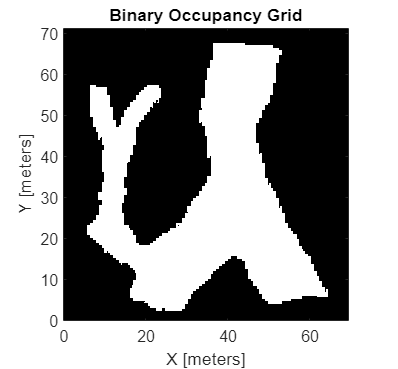

%create occupancy map
occupancy = binaryOccupancyMap((final_field > 0),cells_per_mm);
show(occupancy)

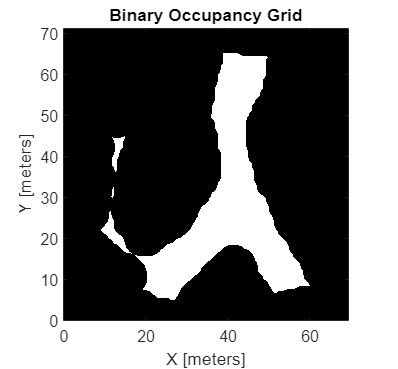

inflate(occupancy,height_mm/2)
show(occupancy)


%inflate obstacles by given amount to represent size of the robot

%create planner
ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);
sv.Map = occupancy;
sv.ValidationDistance = 0.1;
ss.StateBounds = [occupancy.XWorldLimits;occupancy.YWorldLimits;[0 pi]];

planner = plannerRRT(ss,sv,MaxConnectionDistance=0.3);
start = [45 66 0];
goal = [23 6 0];
[pthObj,solnInfo] = plan(planner,start,goal);

Error using plannerRRT/validateStartGoal
Start state is either not valid based on the planner's state validator, or is not finite.
Error in plannerRRT/plan (line 247)
            [startState, goalState] = validateStartGoal( ...

show(occupancy)
hold on
% Tree expansion
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-')
% Draw path
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

Method 2: Create Configuration Space

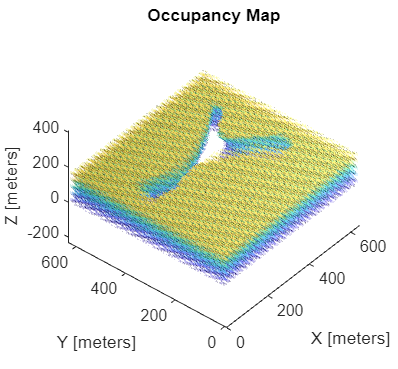


%define dimensions of configuration space
dim = size(final_field);
%set step size for resolution
thetas = 0:5:180;
x_s = 1:5:dim(1);
y_s = 1:5:dim(2);
config_x = length(x_s);
config_y = length(y_s);
config_theta = length(thetas);
config_space_map = occupancyMap3D(1000/pixel_size);
config_space_points = zeros(3,config_x*config_y*config_theta);
index = 1;
%iterate through each configuration to create the config space
for i = 1:config_x
    for j = 1:config_y
        for k = 1:config_theta
            x = x_s(i);
            y = y_s(j);
            theta = thetas(k);
            new_points =rotate_robot(capsule_points,theta);
            collision_check = check_collision(new_points, final_field, [x,y]);
            if collision_check == true
                %config_space(x,y,theta) = 1;
                config_space_points(:,index) = [x_s(i);y_s(j);thetas(k)];
                index = index + 1;
            end
        end
    end
end
%remove points that are not filled
config_space_points = config_space_points(:,1:index);

%create 3d occupancy map
occupancy3d = occupancyMap3D();
setOccupancy(occupancy3d, config_space_points', 1);
show(occupancy3d)


%vol show

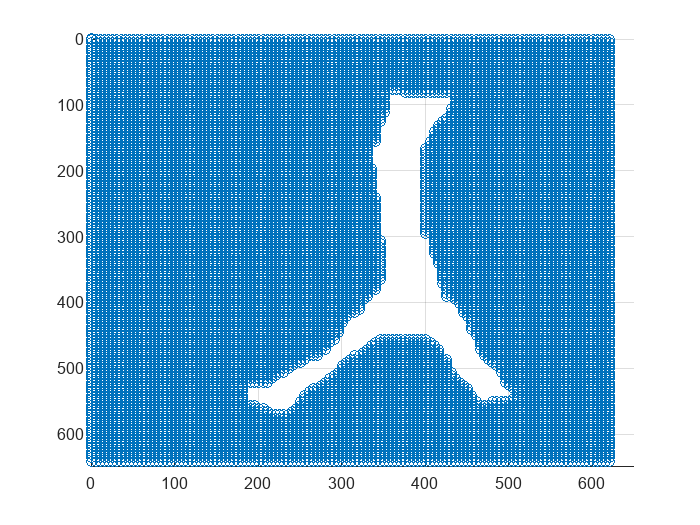


%visualization
figure
for i = thetas
    scatter3(config_space_points(1,:),config_space_points(2,:),config_space_points(3,:))  
    view([90.0 90.0])
    axis([0,650,0,650,i-5,i+5])
    pause(0.25)
end

function collision = check_collision(c_points, map, point)
collision = false;
%initial check if starting point is an obstacle
if (map(point(1),point(2)) == 1)
    collision = true;
else
    %translates the capsule collision points based on the capsule origin point
    trans_points = zeros(size(c_points));
    trans_points(1,:) = c_points(1,:)+point(1);
    trans_points(2,:) = c_points(2,:)+point(2);
    dimension = length(c_points);
    map_dimensions = size(map);
    %iterates through each new capsule point, and checks for collision
    for i = 1:dimension
        a_point = [trans_points(1,i),trans_points(2,i)];
        %make sure there are no negative indices or out of bounds
        if all(a_point > 0) && all(a_point <= [map_dimensions(1),map_dimensions(2)])
            if map(a_point(1),a_point(2)) >= 1
                collision = true;
                return;
            end
        end
    end
end
end

function new_points = rotate_robot(c_points, angle_deg)
%dont rotate if theta is zero
%should save some computation
if angle_deg == 0
    new_points = c_points;
end
rot_z_matrix = [cosd(angle_deg) -sind(angle_deg) 0;
    sind(angle_deg) cosd(angle_deg) 0;
    0 0 1];
new_points = zeros(size(c_points));
dimensions = length(c_points);
for i = 1:dimensions
        rotate_point = rot_z_matrix*[c_points(1,i); c_points(2,i); 0];
        new_points(1,i) = round(rotate_point(1));
        new_points(2,i) = round(rotate_point(2));
end
end